Data Generation - Lorenz

clear;
clc;
clf;

% Parameters
sigma = 10;
beta = 8/3;
rho = 28;
% Time
tspan_lorenz = [0, 20];
dt_lorenz = 0.02;

num_samples_lorenz = 1000;

data_lorenz2 = struct('time', cell(num_samples_lorenz, 1), ...
                     'x', cell(num_samples_lorenz, 1), ...
                     'y', cell(num_samples_lorenz, 1), ...
                     'z', cell(num_samples_lorenz, 1));

for i = 1:num_samples_lorenz
    x_0 = rand() * 20 - 10;
    y_0 = rand() * 20 - 10;
    z_0 = rand() * 20 - 10;
    
    initial_state_lorenz = [x_0, y_0, z_0];
    
    % ODE45 to solve Lorenz system
    [t_lorenz, state_lorenz] = ode45(@(t, y) lorenz_ode(t, y, sigma, beta, rho), tspan_lorenz, initial_state_lorenz);
    
    % Store data
    data_lorenz2(i).time = t_lorenz;
    data_lorenz2(i).x = state_lorenz(:, 1);
    data_lorenz2(i).y = state_lorenz(:, 2);
    data_lorenz2(i).z = state_lorenz(:, 3);    
end

save('data_lorenz_struct2.mat', 'data_lorenz2');

load('data_lorenz_struct2.mat')

data_lorenz2

data_lorenz2 = 1000×1 struct array with fields:
    time
    x
    y
    z


% Ratios for splitting the dataset
train_ratio_lorenz = 0.7;  % 70% for training
val_ratio_lorenz = 0.15;   % 15% for validation
test_ratio_lorenz = 0.15;  % 15% for testing

% Number of samples for each slit
total_samples_lorenz = numel(data_lorenz2);
num_train_lorenz = round(train_ratio_lorenz * total_samples_lorenz);
num_val_lorenz = round(val_ratio_lorenz * total_samples_lorenz);
num_test_lorenz = total_samples_lorenz - num_train_lorenz - num_val_lorenz;

% Shuffling the data randomly
shuffled_data_lorenz = data_lorenz2(randperm(total_samples_lorenz));

% Splitting the data into training, validation, and test sets
training_data_lorenz2 = shuffled_data_lorenz(1:num_train_lorenz);
validation_data_lorenz2 = shuffled_data_lorenz(num_train_lorenz+1:num_train_lorenz+num_val_lorenz);
test_data_lorenz2 = shuffled_data_lorenz(num_train_lorenz+num_val_lorenz+1:end);

% Saving the split datasets to separate MAT files
save('training_data_lorenz2.mat', 'training_data_lorenz2');
save('validation_data_lorenz2.mat', 'validation_data_lorenz2');
save('test_data_lorenz2.mat', 'test_data_lorenz2');

% Load split data
load('training_data_lorenz2.mat');
load('validation_data_lorenz2.mat');
load('test_data_lorenz2.mat');

training_data_lorenz = 700×1 struct array with fields:
    time
    x
    y
    z
    l2_norm


validation_data_lorenz = 150×1 struct array with fields:
    time
    x
    y
    z
    l2_norm


test_data_lorenz = 150×1 struct array with fields:
    time
    x
    y
    z
    l2_norm


% Converting split data from struct to cell for Lorenz system
training_data_lorenz_cell2 = struct2cell(training_data_lorenz2)

training_data_lorenz_cell2 = 4×700 cell array
  Columns 1 through 536

    {989×1 double}    {1213×1 double}    {917×1 double}    {1065×1 double}    {677×1 double}    {1129×1 double}    {825×1 double}    {889×1 double}    {745×1 double}    {1193×1 double}    {1013×1 double}    {1145×1 double}    {917×1 double}    {1025×1 double}    {965×1 double}    {865×1 double}    {1129×1 double}    {981×1 double}    {1201×1 double}    {889×1 double}    {1149×1 double}    {1181×1 double}    {1129×1 double}    {1137×1 double}    {1065×1 double}    {1161×1 double}    {1161×1 double}    {1185×1 double}    {853×1 double}    {705×1 double}    {1213×1 double}    {1213×1 double}    {977×1 double}    {1153×1 double}    {1117×1 double}    {945×1 double}    {881×1 double}    {1109×1 double}    {1105×1 double}    {1185×1 double}    {817×1 double}    {1061×1 double}    {757×1 double}    {1193×1 double}    {905×1 double}    {1113×1 double}    {677×1 double}    {1189×1 double}    {1073×1 double}    {1153×1 double

validation_data_lorenz_cell2 = struct2cell(validation_data_lorenz2)

validation_data_lorenz_cell2 = 4×150 cell array
    {1169×1 double}    {1189×1 double}    {1033×1 double}    {1149×1 double}    {1029×1 double}    {1153×1 double}    {641×1 double}    {645×1 double}    {1221×1 double}    {825×1 double}    {945×1 double}    {1165×1 double}    {729×1 double}    {705×1 double}    {1025×1 double}    {1021×1 double}    {821×1 double}    {1049×1 double}    {1185×1 double}    {993×1 double}    {1061×1 double}    {701×1 double}    {1053×1 double}    {1109×1 double}    {1201×1 double}    {1197×1 double}    {1109×1 double}    {773×1 double}    {1057×1 double}    {737×1 double}    {617×1 double}    {1169×1 double}    {989×1 double}    {909×1 double}    {1189×1 double}    {1093×1 double}    {789×1 double}    {1069×1 double}    {1113×1 double}    {1181×1 double}    {1121×1 double}    {1173×1 double}    {1053×1 double}    {1157×1 double}    {713×1 double}    {1065×1 double}    {1241×1 double}    {1109×1 double}    {1113×1 double}    {837×1 double}    {1217×1 double}

test_data_lorenz_cell2 = struct2cell(test_data_lorenz2)

test_data_lorenz_cell2 = 4×150 cell array
    {1145×1 double}    {1001×1 double}    {697×1 double}    {853×1 double}    {1221×1 double}    {1141×1 double}    {801×1 double}    {745×1 double}    {1173×1 double}    {1121×1 double}    {1017×1 double}    {1037×1 double}    {969×1 double}    {1133×1 double}    {1177×1 double}    {1217×1 double}    {1041×1 double}    {985×1 double}    {1193×1 double}    {1089×1 double}    {1065×1 double}    {1097×1 double}    {1049×1 double}    {1233×1 double}    {913×1 double}    {1045×1 double}    {693×1 double}    {633×1 double}    {1217×1 double}    {1185×1 double}    {1149×1 double}    {1053×1 double}    {1021×1 double}    {797×1 double}    {905×1 double}    {961×1 double}    {881×1 double}    {773×1 double}    {1229×1 double}    {1121×1 double}    {1197×1 double}    {1169×1 double}    {1133×1 double}    {1049×1 double}    {1133×1 double}    {861×1 double}    {621×1 double}    {1213×1 double}    {865×1 double}    {1209×1 double}    {961×1 double}    {84

% Transposing cell arrays
training_data_lorenz_cell2 = training_data_lorenz_cell2'

training_data_lorenz_cell2 = 700×4 cell array
    { 989×1 double}    { 989×1 double}    { 989×1 double}    { 989×1 double}
    {1213×1 double}    {1213×1 double}    {1213×1 double}    {1213×1 double}
    { 917×1 double}    { 917×1 double}    { 917×1 double}    { 917×1 double}
    {1065×1 double}    {1065×1 double}    {1065×1 double}    {1065×1 double}
    { 677×1 double}    { 677×1 double}    { 677×1 double}    { 677×1 double}
    {1129×1 double}    {1129×1 double}    {1129×1 double}    {1129×1 double}
    { 825×1 double}    { 825×1 double}    { 825×1 double}    { 825×1 double}
    { 889×1 double}    { 889×1 double}    { 889×1 double}    { 889×1 double}
    { 745×1 double}    { 745×1 double}    { 745×1 double}    { 745×1 double}
    {1193×1 double}    {1193×1 double}    {1193×1 double}    {1193×1 double}
    {1013×1 double}    {1013×1 double}    {1013×1 double}    {1013×1 double}
    {1145×1 double}    {1145×1 double}    {1145×1 double}    {1145×1 double}
    { 917×1 double}    { 917×1

validation_data_lorenz_cell2 = validation_data_lorenz_cell2'

validation_data_lorenz_cell2 = 150×4 cell array
    {1169×1 double}    {1169×1 double}    {1169×1 double}    {1169×1 double}
    {1189×1 double}    {1189×1 double}    {1189×1 double}    {1189×1 double}
    {1033×1 double}    {1033×1 double}    {1033×1 double}    {1033×1 double}
    {1149×1 double}    {1149×1 double}    {1149×1 double}    {1149×1 double}
    {1029×1 double}    {1029×1 double}    {1029×1 double}    {1029×1 double}
    {1153×1 double}    {1153×1 double}    {1153×1 double}    {1153×1 double}
    { 641×1 double}    { 641×1 double}    { 641×1 double}    { 641×1 double}
    { 645×1 double}    { 645×1 double}    { 645×1 double}    { 645×1 double}
    {1221×1 double}    {1221×1 double}    {1221×1 double}    {1221×1 double}
    { 825×1 double}    { 825×1 double}    { 825×1 double}    { 825×1 double}
    { 945×1 double}    { 945×1 double}    { 945×1 double}    { 945×1 double}
    {1165×1 double}    {1165×1 double}    {1165×1 double}    {1165×1 double}
    { 729×1 double}    { 729

test_data_lorenz_cell2 = test_data_lorenz_cell2'

test_data_lorenz_cell2 = 150×4 cell array
    {1145×1 double}    {1145×1 double}    {1145×1 double}    {1145×1 double}
    {1001×1 double}    {1001×1 double}    {1001×1 double}    {1001×1 double}
    { 697×1 double}    { 697×1 double}    { 697×1 double}    { 697×1 double}
    { 853×1 double}    { 853×1 double}    { 853×1 double}    { 853×1 double}
    {1221×1 double}    {1221×1 double}    {1221×1 double}    {1221×1 double}
    {1141×1 double}    {1141×1 double}    {1141×1 double}    {1141×1 double}
    { 801×1 double}    { 801×1 double}    { 801×1 double}    { 801×1 double}
    { 745×1 double}    { 745×1 double}    { 745×1 double}    { 745×1 double}
    {1173×1 double}    {1173×1 double}    {1173×1 double}    {1173×1 double}
    {1121×1 double}    {1121×1 double}    {1121×1 double}    {1121×1 double}
    {1017×1 double}    {1017×1 double}    {1017×1 double}    {1017×1 double}
    {1037×1 double}    {1037×1 double}    {1037×1 double}    {1037×1 double}
    { 969×1 double}    { 969×1 dou

save('test_data_lorenz_cell2.mat', 'test_data_lorenz_cell2');

test_data_lorenz_cell2

test_data_lorenz_cell2 = 4×150 cell array
    {1129×1 double}    {1237×1 double}    {1121×1 double}    {917×1 double}    {1169×1 double}    {1121×1 double}    {1205×1 double}    {629×1 double}    {1061×1 double}    {1057×1 double}    {1185×1 double}    {925×1 double}    {1089×1 double}    {1117×1 double}    {1085×1 double}    {829×1 double}    {1085×1 double}    {1085×1 double}    {1117×1 double}    {877×1 double}    {1149×1 double}    {949×1 double}    {1085×1 double}    {1157×1 double}    {853×1 double}    {1149×1 double}    {1177×1 double}    {885×1 double}    {1205×1 double}    {869×1 double}    {1153×1 double}    {1217×1 double}    {1061×1 double}    {1145×1 double}    {661×1 double}    {1065×1 double}    {1165×1 double}    {1129×1 double}    {1045×1 double}    {805×1 double}    {881×1 double}    {1185×1 double}    {1193×1 double}    {1213×1 double}    {1197×1 double}    {1085×1 double}    {761×1 double}    {749×1 double}    {1165×1 double}    {1157×1 double}    {1125×1 double}   

% Converting training data from cell to matrix for Lorenz system
originalTrainingDataLorenz = cell2mat(training_data_lorenz)

originalTrainingDataLorenz =          0   -1.2650    1.4451    1.3013    2.3199
    0.0021   -1.2104    1.3741    1.2906    2.2403
    0.0041   -1.1584    1.3061    1.2803    2.1649
    0.0062   -1.1088    1.2410    1.2703    2.0936
    0.0082   -1.0615    1.1787    1.2606    2.0262
    0.0173   -0.8783    0.9346    1.2214    1.7711
    0.0264   -0.7303    0.7323    1.1863    1.5738
    0.0354   -0.6114    0.5642    1.1542    1.4228
    0.0445   -0.5162    0.4233    1.1242    1.3075
    0.0531   -0.4436    0.3094    1.0972    1.2233



% Number of sequences for Lorenz system
NLorenz = size(originalTrainingDataLorenz, 1);

% Cell array to hold the sequences for Lorenz system
newTrainingDataLorenz1 = cell(NLorenz, 1);

% Populating the cell array with sequences for Lorenz system
for i = 1:NLorenz
    newTrainingDataLorenz1{i} = originalTrainingDataLorenz(i, :);
end
newTrainingDataLorenz1

newTrainingDataLorenz1 = 713644×1 cell array
    {[      0 -1.2650 1.4451 1.3013 2.3199]}
    {[ 0.0021 -1.2104 1.3741 1.2906 2.2403]}
    {[ 0.0041 -1.1584 1.3061 1.2803 2.1649]}
    {[ 0.0062 -1.1088 1.2410 1.2703 2.0936]}
    {[ 0.0082 -1.0615 1.1787 1.2606 2.0262]}
    {[ 0.0173 -0.8783 0.9346 1.2214 1.7711]}
    {[ 0.0264 -0.7303 0.7323 1.1863 1.5738]}
    {[ 0.0354 -0.6114 0.5642 1.1542 1.4228]}
    {[ 0.0445 -0.5162 0.4233 1.1242 1.3075]}
    {[ 0.0531 -0.4436 0.3094 1.0972 1.2233]}
    {[ 0.0617 -0.3857 0.2114 1.0715 1.1582]}
    {[ 0.0703 -0.3402 0.1262 1.0467 1.1078]}
    {[ 0.0789 -0.3051 0.0509 1.0227 1.0685]}
    {[0.0871 -0.2796 -0.0141 1.0004 1.0389]}
    {[0.0953 -0.2610 -0.0738 0.9788 1.0157]}
    {[0.1036 -0.2484 -0.1296 0.9577 0.9979]}


save('newTrainingDataLorenz1.mat', 'newTrainingDataLorenz1');

% Converting training data from cell to matrix for Lorenz system
originalTrainingDataLorenz = cell2mat(training_data_lorenz)

originalTrainingDataLorenz =          0   -1.2650    1.4451    1.3013    2.3199
    0.0021   -1.2104    1.3741    1.2906    2.2403
    0.0041   -1.1584    1.3061    1.2803    2.1649
    0.0062   -1.1088    1.2410    1.2703    2.0936
    0.0082   -1.0615    1.1787    1.2606    2.0262
    0.0173   -0.8783    0.9346    1.2214    1.7711
    0.0264   -0.7303    0.7323    1.1863    1.5738
    0.0354   -0.6114    0.5642    1.1542    1.4228
    0.0445   -0.5162    0.4233    1.1242    1.3075
    0.0531   -0.4436    0.3094    1.0972    1.2233



% Number of sequences for Lorenz system
NLorenz = size(originalTrainingDataLorenz, 1);

% Cell array to hold the sequences for Lorenz system
newTrainingDataLorenz2 = cell(NLorenz, 1);

% Populating the cell array with sequences for Lorenz system
for i = 1:NLorenz
    newTrainingDataLorenz2{i} = originalTrainingDataLorenz(i, :);
end
newTrainingDataLorenz2

newTrainingDataLorenz2 = 713644×1 cell array
    {[      0 -1.2650 1.4451 1.3013 2.3199]}
    {[ 0.0021 -1.2104 1.3741 1.2906 2.2403]}
    {[ 0.0041 -1.1584 1.3061 1.2803 2.1649]}
    {[ 0.0062 -1.1088 1.2410 1.2703 2.0936]}
    {[ 0.0082 -1.0615 1.1787 1.2606 2.0262]}
    {[ 0.0173 -0.8783 0.9346 1.2214 1.7711]}
    {[ 0.0264 -0.7303 0.7323 1.1863 1.5738]}
    {[ 0.0354 -0.6114 0.5642 1.1542 1.4228]}
    {[ 0.0445 -0.5162 0.4233 1.1242 1.3075]}
    {[ 0.0531 -0.4436 0.3094 1.0972 1.2233]}
    {[ 0.0617 -0.3857 0.2114 1.0715 1.1582]}
    {[ 0.0703 -0.3402 0.1262 1.0467 1.1078]}
    {[ 0.0789 -0.3051 0.0509 1.0227 1.0685]}
    {[0.0871 -0.2796 -0.0141 1.0004 1.0389]}
    {[0.0953 -0.2610 -0.0738 0.9788 1.0157]}
    {[0.1036 -0.2484 -0.1296 0.9577 0.9979]}


% Saving the new training data for Lorenz system to a MAT file
save('newTrainingDataLorenz2.mat', 'newTrainingDataLorenz2');

% Converting validation data from cell to matrix for Lorenz system
originalValidationDataLorenz = cell2mat(validation_data_lorenz);

% Number of sequences for Lorenz system
MLorenz = size(originalValidationDataLorenz, 1);

% Cell array to hold the sequences for Lorenz system
newValidationDataLorenz = cell(NLorenz, 1);

% Populating the cell array with sequences for Lorenz system
for i = 1:MLorenz
    newValidationDataLorenz{i} = originalValidationDataLorenz(i, :);
end

% Displaying the new validation data for Lorenz system
newValidationDataLorenz

newValidationDataLorenz = 713644×1 cell array
    {[     0 -9.5740 7.5997 5.9634 13.6007]}
    {[0.0017 -9.2799 7.2227 5.8140 13.1182]}
    {[0.0035 -8.9974 6.8552 5.6749 12.6551]}
    {[0.0052 -8.7260 6.4970 5.5454 12.2109]}
    {[0.0070 -8.4655 6.1479 5.4249 11.7852]}
    {[ 0.0157 -7.3125 4.5324 4.9364 9.9188]}
    {[ 0.0245 -6.3828 3.1117 4.5978 8.4595]}
    {[ 0.0332 -5.6437 1.8570 4.3653 7.3727]}
    {[ 0.0419 -5.0655 0.7391 4.2062 6.6255]}
    {[0.0510 -4.6073 -0.3101 4.0958 6.1725]}
    {[0.0601 -4.2762 -1.2684 4.0294 6.0109]}
    {[0.0692 -4.0549 -2.1594 3.9977 6.0899]}
    {[0.0783 -3.9283 -3.0051 3.9949 6.3578]}
    {[0.0870 -3.8844 -3.7905 4.0173 6.7524]}
    {[0.0957 -3.9092 -4.5659 4.0651 7.2563]}
    {[0.1044 -3.9970 -5.3438 4.1403 7.8533]}


save('newValidationDataLorenz.mat', 'newValidationDataLorenz');

% Original Test data for Lorenz system
originalTestDataLorenz = cell2mat(test_data_lorenz);

% Number of sequences for Lorenz system
LLorenz = size(originalTestDataLorenz, 1);

% Cell array to hold the sequences for Lorenz system
newTestDataLorenz = cell(NLorenz, 1);

% Populating the cell array with sequences for Lorenz system
for i = 1:LLorenz
    newTestDataLorenz{i} = originalTestDataLorenz(i, :);
end

% Displaying the new validation data for Lorenz system
newTestDataLorenz

newTestDataLorenz = 713644×1 cell array
    {[         0 7.7392 3.1486 3.6903 9.1339]}
    {[8.5508e-04 7.7008 3.3063 3.7032 9.1623]}
    {[    0.0017 7.6641 3.4630 3.7170 9.1949]}
    {[    0.0026 7.6290 3.6187 3.7316 9.2315]}
    {[    0.0034 7.5955 3.7734 3.7472 9.2721]}
    {[    0.0077 7.4516 4.5340 3.8375 9.5295]}
    {[    0.0120 7.3452 5.2754 3.9483 9.8676]}
    {[   0.0162 7.2739 6.0006 4.0787 10.2739]}
    {[   0.0205 7.2357 6.7128 4.2284 10.7376]}
    {[   0.0311 7.2708 8.4418 4.6846 12.0861]}
    {[  0.0417 7.4752 10.1421 5.2704 13.6572]}
    {[  0.0523 7.8312 11.8380 6.0035 15.4113]}
    {[  0.0629 8.3227 13.5462 6.9082 17.3346]}
    {[  0.0745 8.9953 15.4246 8.1237 19.6171]}
    {[  0.0860 9.8003 17.3096 9.6265 22.0984]}
    {[0.0976 10.7229 19.1657 11.4632 24.7731]}


save('newTestDataLorenz.mat', 'newValidationDataLorenz');

% Finding the dimension
dimension2 = size(newTrainingDataLorenz{1});

% Validation data preprocessing
for i = 1:length(newValidationDataLorenz)
    if ~isequal(size(newValidationDataLorenz{i}), dimension2)
        % Pad the validation data
        newValidationDataLorenz{i} = padarray(newValidationDataLorenz{i}, dimension2 - size(newValidationDataLorenz{i}), 0, 'post');
    end
end
newValidationDataLorenz

newValidationDataLorenz = 713644×1 cell array
    {[     0 -9.5740 7.5997 5.9634 13.6007]}
    {[0.0017 -9.2799 7.2227 5.8140 13.1182]}
    {[0.0035 -8.9974 6.8552 5.6749 12.6551]}
    {[0.0052 -8.7260 6.4970 5.5454 12.2109]}
    {[0.0070 -8.4655 6.1479 5.4249 11.7852]}
    {[ 0.0157 -7.3125 4.5324 4.9364 9.9188]}
    {[ 0.0245 -6.3828 3.1117 4.5978 8.4595]}
    {[ 0.0332 -5.6437 1.8570 4.3653 7.3727]}
    {[ 0.0419 -5.0655 0.7391 4.2062 6.6255]}
    {[0.0510 -4.6073 -0.3101 4.0958 6.1725]}
    {[0.0601 -4.2762 -1.2684 4.0294 6.0109]}
    {[0.0692 -4.0549 -2.1594 3.9977 6.0899]}
    {[0.0783 -3.9283 -3.0051 3.9949 6.3578]}
    {[0.0870 -3.8844 -3.7905 4.0173 6.7524]}
    {[0.0957 -3.9092 -4.5659 4.0651 7.2563]}
    {[0.1044 -3.9970 -5.3438 4.1403 7.8533]}


save('newValidationDataLorenz.mat', 'newValidationDataLorenz');

% LSTM network
inputSize = 1;       
numHiddenUnits = 20; 
outputSize = 1;     

layers = [
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits, 'OutputMode', 'sequence')
    fullyConnectedLayer(outputSize)
    regressionLayer
];

% Training options
options = trainingOptions('adam', ...
    'InitialLearnRate',0.2,...
    'MaxEpochs', 2, ...
    'MiniBatchSize', 3200, ...
    'ValidationData', {newValidationDataLorenz, newValidationDataLorenz}, ...
    'ValidationFrequency', 10, ...
    'Plots', 'training-progress', ...
    'Verbose', true, ...
    'ExecutionEnvironment', 'gpu');  

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:24 |        18.90 |         7.50 |     178.5240 |      28.1485 |          0.2000 |
|       1 |          10 |       00:00:41 |         7.44 |         3.57 |      27.6612 |       6.3830 |          0.2000 |
|       1 |          20 |       00:00:57 |         4.17 |         3.21 |       8.6972 |       5.1413 |          0.2000 |
|       1 |          30 |       00:01:14 |         2.37 |         2.18 |       2.7991 |       2.3711 |          0.2000 |
|       1 |          40 |       

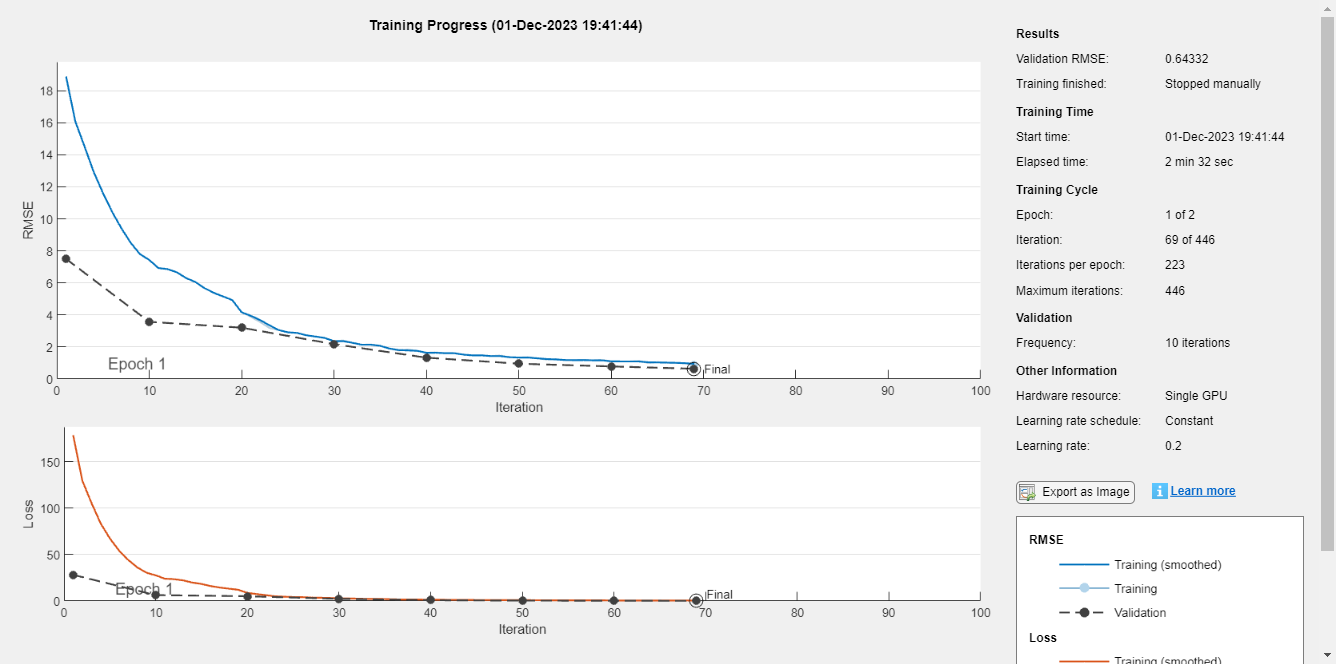

% Train the LSTM network
net222 = trainNetwork(newTrainingDataLorenz, newTrainingDataLorenz, layers, options);

save('trained_network16.mat', 'net16')